# Cinematica Inversa

Parametros iniciales

L1 = 13.8;
L2 = 10.6;
L3 = 10.6;
L4 = 10.9;
P = [22 5 17];
Theta = 0;

Desacople de 4 gdl a 3 gdl

xp = P(1);
yp = P(2);
zp = P(3);
wp = sqrt(xp^2 + yp^2);
zt = zp - L4*sind(Theta);
wt = wp - L4*cosd(Theta);

Calculo del ángulo 1

alpha1 = atan2d(yp,xp)

alpha1 = 12.8043

Calculo de los ángulos 2,  3 y 4 en codo arriba

z0 = zt - L1;
r2 = wt^2 + z0^2;
c_alpha3 = (r2 - L2^2 - L3^2)/(2*L2*L3);
s_alpha3 = -sqrt(1 - c_alpha3^2);
k1 = L2 + L3*c_alpha3;
k2 = L3*abs(s_alpha3);
alpha2 = atan2d(z0,wt) + atan2d(k2,k1)

alpha2 = 70.5683

alpha3 = atan2d(s_alpha3,c_alpha3)

alpha3 = -110.4461

alpha4 = Theta - alpha2 -alpha3

alpha4 = 39.8778

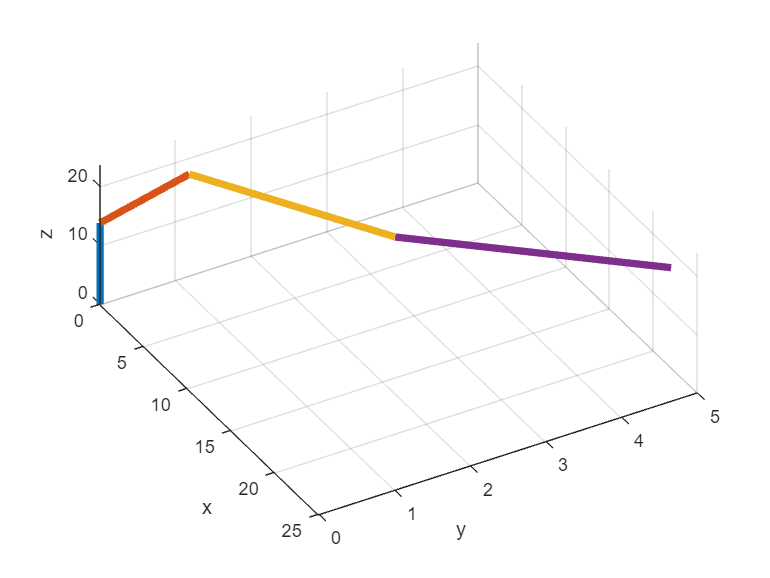

figure
hold on
plot3([0 0],[0 0],[0 L1],"LineWidth",4)
w2 = L2*cosd(alpha2);
x2 = w2*cosd(alpha1);
y2 = w2*sind(alpha1);
z2 = L1 + L2*sind(alpha2);
plot3([0 x2],[0 y2],[L1 z2],"LineWidth",4)
w3 = w2 + L3*cosd(alpha2+alpha3);
x3 = w3*cosd(alpha1);
y3 = w3*sind(alpha1);
z3 = z2 + L3*sind(alpha2+alpha3);
plot3([x2 x3],[y2 y3],[z2 z3],"LineWidth",4)
w4 = w3 + L4*cosd(alpha2+alpha3+alpha4);
x4 = w4*cosd(alpha1);
y4 = w4*sind(alpha1);
z4 = z3 + L4*sind(alpha2+alpha3+alpha4);
plot3([x3 x4],[y3 y4],[z3 z4],"LineWidth",4)
grid on
view(60,60)
xlabel('x');
ylabel('y');
zlabel('z');
hold off

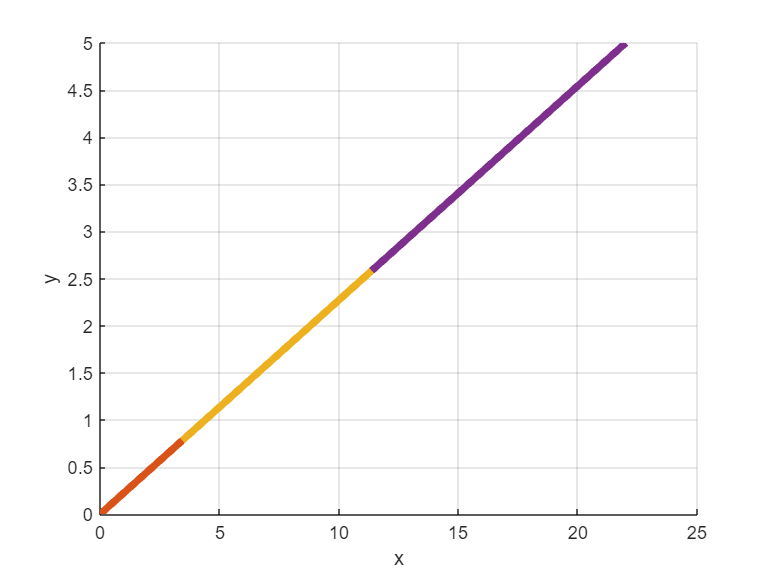

figure
hold on
plot([ 0  0],[ 0  0],"LineWidth",4)
plot([ 0 x2],[ 0 y2],"LineWidth",4)
plot([x2 x3],[y2 y3],"LineWidth",4)
plot([x3 x4],[y3 y4],"LineWidth",4)
grid on
xlabel('x');
ylabel('y');
hold off

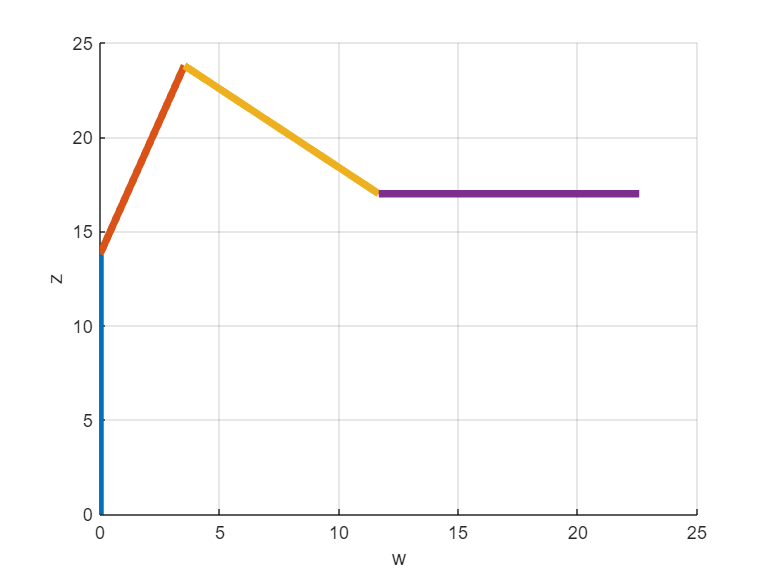

figure
hold on
plot([ 0  0],[ 0 L1],"LineWidth",4)
plot([ 0 w2],[L1 z2],"LineWidth",4)
plot([w2 w3],[z2 z3],"LineWidth",4)
plot([w3 w4],[z3 z4],"LineWidth",4)
grid on
xlabel('w');
ylabel('z');
hold off

Conversión de alpha a q

q1 = alpha1;
q2 = alpha2 - 90; %Offset de +90° con el suelo
q3 = alpha3; % alpha3 + 90 = Offset de -90° con link2
q4 = alpha4;
q_car = [q1 q2 q3 q4]

q_car =    12.8043  -19.4317 -110.4461   39.8778


q_car_bit = Angle2Bit(0,q_car) 

q_car_bit =    555   445   134   648


CinematicaInversaPhantom(P,Theta)

ans =    12.8043
  -20.9108
 -111.8876
   42.7984


VerificarAlcanzabilidad(P,Theta,q_car)

ans = logical
   1

Calculo de los ángulos 2,  3 y 4 en codo abajo

z0 = zt - L1;
r2 = wt^2 + z0^2;
c_alpha3 = (r2 - L2^2 - L3^2)/(2*L2*L3);
s_alpha3 = sqrt(1 - c_alpha3^2);
k1 = L2 + L3*c_alpha3;
k2 = L3*s_alpha3;
alpha2 = atan2d(z0,wt) - atan2d(k2,k1)

alpha2 = -39.8778

alpha3 = atan2d(s_alpha3,c_alpha3)

alpha3 = 110.4461

alpha4 = Theta - alpha2 -alpha3

alpha4 = -70.5683

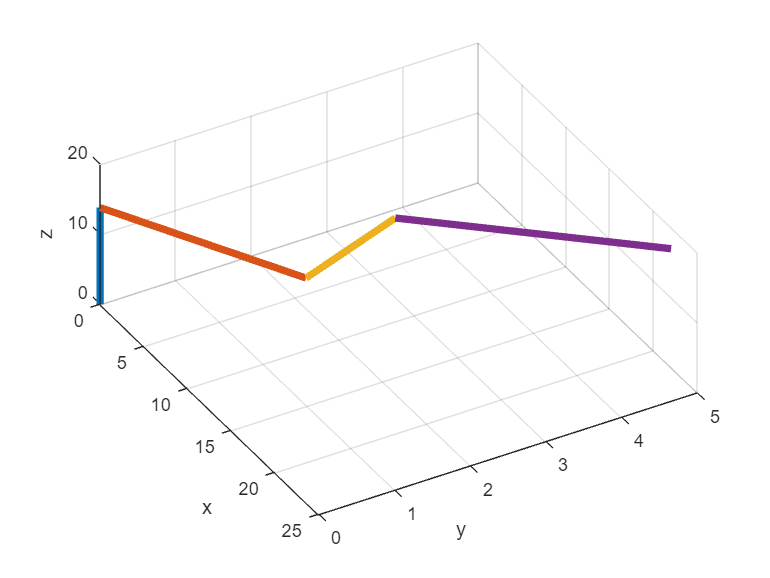

figure
hold on
plot3([0 0],[0 0],[0 L1],"LineWidth",4)
w2 = L2*cosd(alpha2);
x2 = w2*cosd(alpha1);
y2 = w2*sind(alpha1);
z2 = L1 + L2*sind(alpha2);
plot3([0 x2],[0 y2],[L1 z2],"LineWidth",4)
w3 = w2 + L3*cosd(alpha2+alpha3);
x3 = w3*cosd(alpha1);
y3 = w3*sind(alpha1);
z3 = z2 + L3*sind(alpha2+alpha3);
plot3([x2 x3],[y2 y3],[z2 z3],"LineWidth",4)
w4 = w3 + L4*cosd(alpha2+alpha3+alpha4);
x4 = w4*cosd(alpha1);
y4 = w4*sind(alpha1);
z4 = z3 + L4*sind(alpha2+alpha3+alpha4);
plot3([x3 x4],[y3 y4],[z3 z4],"LineWidth",4)
grid on
view(60,60)
xlabel('x');
ylabel('y');
zlabel('z');
hold off

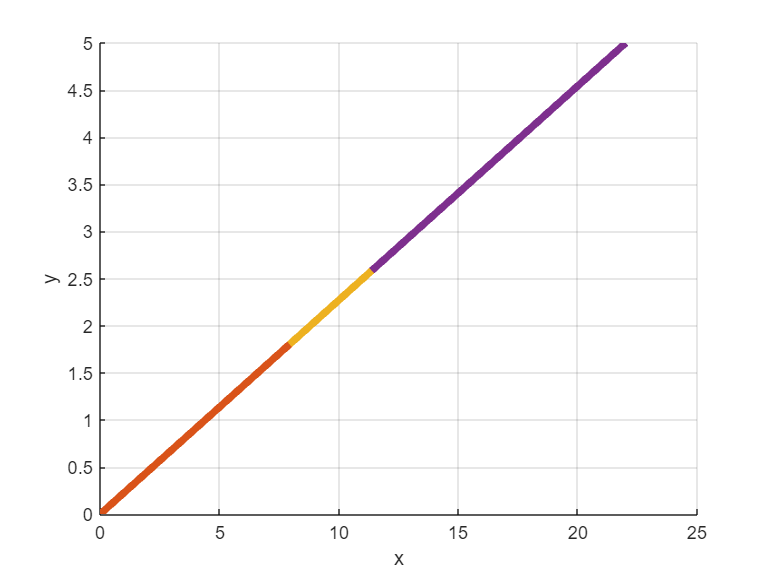

figure
hold on
plot([ 0  0],[ 0  0],"LineWidth",4)
plot([ 0 x2],[ 0 y2],"LineWidth",4)
plot([x2 x3],[y2 y3],"LineWidth",4)
plot([x3 x4],[y3 y4],"LineWidth",4)
grid on
xlabel('x');
ylabel('y');
hold off

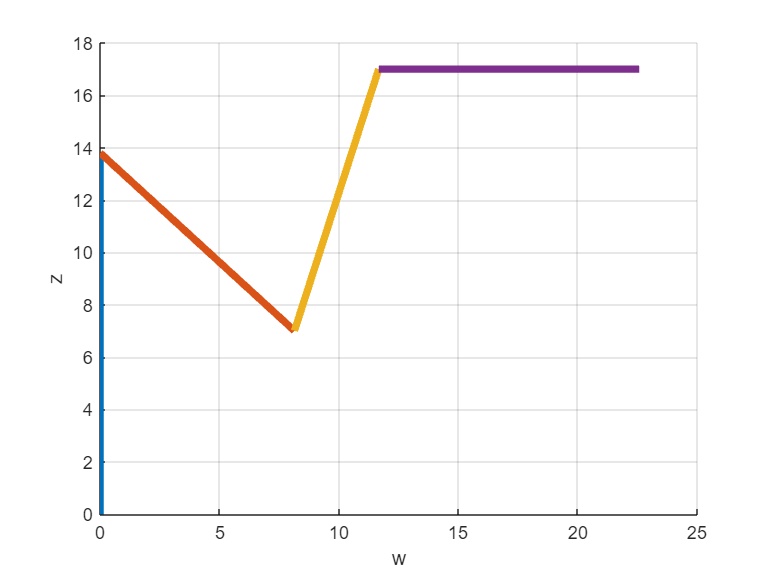

figure
hold on
plot([ 0  0],[ 0 L1],"LineWidth",4)
plot([ 0 w2],[L1 z2],"LineWidth",4)
plot([w2 w3],[z2 z3],"LineWidth",4)
plot([w3 w4],[z3 z4],"LineWidth",4)
grid on
xlabel('w');
ylabel('z');
hold off

Conversión de alpha a q

q1 = alpha1;
q2 = alpha2 - 90; %Offset de +90° con el suelo
q3 = alpha3; %alpha3 + 90 Offset de -90° con link2
q4 = alpha4;
q_cab = [q1 q2 q3 q4]

q_cab =    12.8043 -129.8778  110.4461  -70.5683


q_cab_bit = Angle2Bit(0,q_cab) 

q_cab_bit =    555    67   889   270


VerificarAlcanzabilidad(P,Theta,q_cab)

ans = logical
   1